# FUELSTEPWISE

Fit and evaluate linear models of fuel economy using stepwise fitting.

## Load data

load carEcon

## Perform a stepwise linear fit of fuel economy

mdl = stepwiselm(carTrain);

1. Adding City_Highway, FStat = 1103.1943, pValue = 2.6005394e-184
2. Adding EngDisp, FStat = 2783.0129, pValue = 0
3. Adding FuelType, FStat = 84.721, pValue = 8.03591e-105
4. Adding EngDisp:City_Highway, FStat = 347.5023, pValue = 2.768531e-70
5. Adding Drive, FStat = 136.4937, pValue = 2.038924e-55
6. Adding Transmission, FStat = 14.0464, pValue = 4.80023e-36
7. Adding Weight, FStat = 277.8036, pValue = 1.508394e-57
8. Adding Valves_Cyl, FStat = 123.5276, pValue = 1.123981e-27
9. Adding Transmission:Valves_Cyl, FStat = 10.6438, pValue = 1.45971e-20
10. Adding Transmission:Weight, FStat = 8.2467, pValue = 2.3888e-18
11. Adding AC, FStat = 75.332, pValue = 9.95502e-18
12. Adding City_Highway:Valves_Cyl, FStat = 61.4004, pValue = 8.62951e-15
13. Adding FuelType:City_Highway, FStat = 15.0735, pValue = 1.78455e-14
14. Adding Drive:Valves_Cyl, FStat = 32.6624, pValue = 1.28641e-14
15. Adding RatedHP, FStat = 77.7732, pValue = 3.08367e-18
16. Adding Comp, FStat = 70.5003, pValue = 1.03598e

## Evaluate model at test predictor values

resppred = predict(mdl,carTest);

## Compare predicted and actual responses

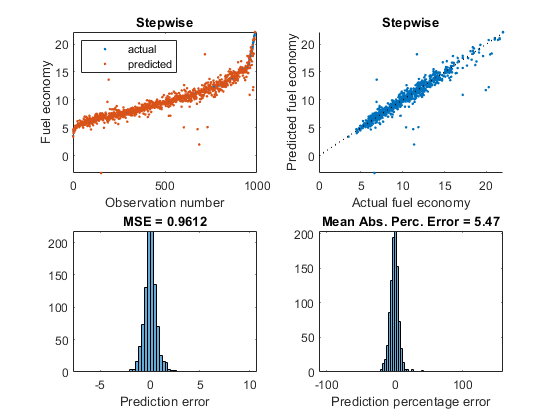

evaluatefit(carTest.FuelEcon,resppred,'Stepwise')
subplot(2,2,1)
legend(["actual","predicted"],"Location","northwest")

## Change criterion and limit to linear models

mdl = stepwiselm(carTrain,'Criterion','aic','Upper','linear');

1. Adding City_Highway, AIC = 7569.9708
2. Adding EngDisp, AIC = 5958.8092
3. Adding FuelType, AIC = 5465.7601
4. Adding Drive, AIC = 5266.4306
5. Adding Transmission, AIC = 5128.8571
6. Adding Weight, AIC = 4917.1443
7. Adding Valves_Cyl, AIC = 4818.3178
8. Adding AC, AIC = 4777.5444
9. Adding RatedHP, AIC = 4714.5474
10. Adding Car_Truck, AIC = 4667.2642
11. Adding Comp, AIC = 4648.3942
12. Adding EVSpeedRatio, AIC = 4630.1235
13. Adding AxleRatio, AIC = 4627.0008


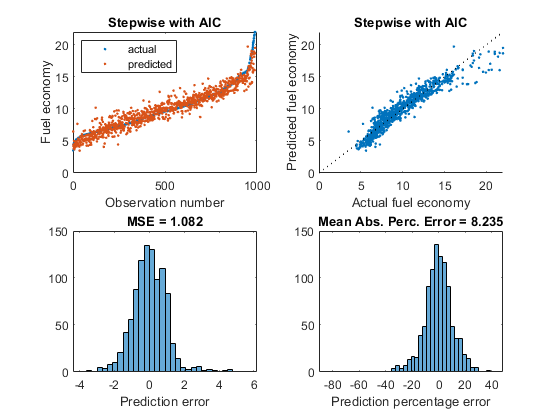

resppred = predict(mdl,carTest);
evaluatefit(carTest.FuelEcon,resppred,'Stepwise with AIC')
subplot(2,2,1)
legend(["actual","predicted"],"Location","northwest")